 
global kp ki kd q r;
q=1;
r=1;

 
T_osc=5/3;
ku=75.5;
kp=0.5*ku % 12.5

kp = 37.7500

ki=0;
kd=0;

 
T_osc=5/3;
ku=75.5;
kp=0.45*ku % 11.2500

kp = 33.9750

ki=0.54*ku*T_osc^(-1) %5.1923

ki = 24.4620

kd=0;

 
T_osc=2.6;
ku=25;
kp=0.8*ku % 20

kp = 20

kd=0.1*ku*T_osc % 6.5000

kd = 6.5000

ki=0

ki = 0

 
T_osc=2.6;
ku=25;
kp=0.6*ku % 15

kp = 15

ki=1.2*ku*T_osc^(-1) % 11.5385

ki = 11.5385

kd=0.075*ku*T_osc % 4.8750

kd = 4.8750

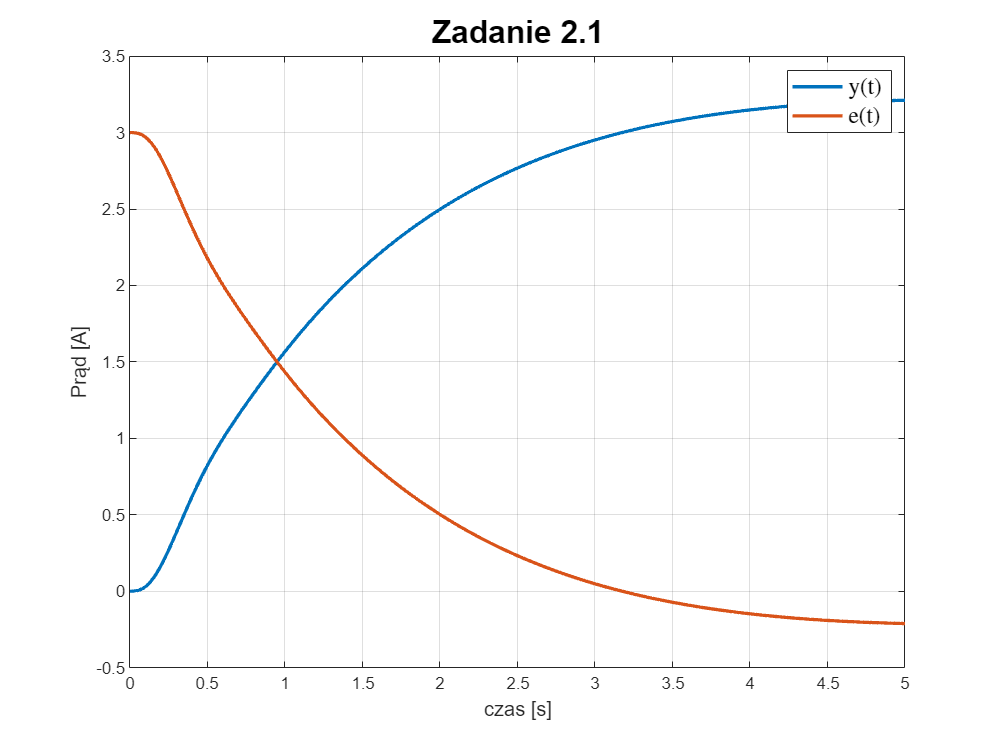

kp=40;
ki=10.2;
kd=50;
 
tspan = linspace(0,5,1000);
x0 = zeros(9,1);
[t, y] = ode45(@model, tspan, x0);
yd=3;
Zadanie2 = figure('Position', [10 10 800 600]);
plot(t, y(:, 2), 'LineWidth', 2)
hold on
plot(t, yd-y(:,2), 'LineWidth', 2)
xlabel('czas [s]', 'FontSize', 12)
ylabel('Prąd [A]', 'FontSize', 12)
lgd = legend('y(t)', 'e(t)', 'Interpreter', 'latex');
title('Zadanie 2.1', 'FontSize', 19)
fontsize(lgd, 14, 'points')
grid on

ISE=max(y(:,5));
ITSE=max(y(:,6));
IAE=max(y(:,7));
ITAE=max(y(:,8));
IOE=max(y(:,9));
disp("ISE="+num2str(ISE))

ISE=6.2715


disp("ITSE="+num2str(ITSE))

ITSE=3.5435


disp("IAE="+num2str(IAE))

IAE=3.653


disp("ITAE="+num2str(ITAE))

ITAE=3.9595


disp("IOE="+num2str(IOE))

IOE=39.6197


 
q=1

q = 1

r=0.01

r = 0.0100

 
q=1

q = 1

r=1

r = 1

 
kp_vec=40:0.5:80;
ki_vec=10:0.5:50;
kd_vec=10:0.5:50;
r_vec=[1 0.01];
ISE_min=100000;
IOE_min=100000;
kp_IOE=0

kp_IOE = 0

ki_IOE=0

ki_IOE = 0

kd_IOE=0

kd_IOE = 0

kp_ISE=0

kp_ISE = 0

ki_ISE=0

ki_ISE = 0

kd_ISE=0

kd_ISE = 0

for g=1:length(r_vec)
    r=r_vec(g)
    for i=1:length(kp_vec)
        kp=kp_vec(i);
        for j=1:length(ki_vec)
            ki=ki_vec(j);
            for k=1:length(kd_vec)
                kd=kd_vec(k);
                tspan = [0 5];
                x0 = zeros(9,1);
                [t, y] = ode45(@model, tspan, x0);
                ISE=max(y(:,5));
                IOE=max(y(:,9));
                if(ISE<ISE_min)
                    ISE_min=ISE;
                    kp_ISE=kp;
                    ki_ISE=ki;
                    kd_ISE=kd;
                end
                if(IOE<IOE_min)
                    IOE_min=IOE;
                    kp_IOE=kp;
                    ki_IOE=ki;
                    kd_IOE=kd;
                end
            end
        end
    end
end

r = 1

r = 0.0100

disp("kp_ISE="+num2str(kp_ISE))

kp_ISE=80


disp("ki_ISE="+num2str(ki_ISE))

ki_ISE=19


disp("kd_ISE="+num2str(kd_ISE))

kd_ISE=22


function dxdt = model(t, x)
    % Parametry układu
    R1 = 2;
    R2 = 5;
    C1 = 0.5;
    L1 = 2;
    L2 = 0.5;
    global r q;
    % Regulator PID
    global kp ki kd
    yd = 3;
    e=yd-x(2);
    e_prim= -R2/L2 * x(2) + 1/L2 * x(3);
    u=kp*e+ki*x(4)+kd*(-e_prim);
    % Obliczenia
    dxdt = zeros(9, 1);
    % -R1 / L1 * x1 - 1 / L1 * x3 + 1 / L1 * u
    dxdt(1) = -R1/L1 * x(1) - 1/L1 * x(3) + 1/L1 * u;
    % -R2 / L2 * x2 + 1 / L2 * x3
    dxdt(2) = - R2/L2 * x(2) + 1/L2 * x(3);
    % 1 / C1 * x1 - 1 / C1 * x2
    dxdt(3) = 1/C1 * x(1) - 1/C1 * x(2);
    % e
    dxdt(4) = e;
    %Kryteria całkowe, po kolei
    dxdt(5) = e^2; %ISE
    dxdt(6) = t*e^2; %ITSE
    dxdt(7) = abs(e); %IAE
    dxdt(8) = t*abs(e); %ITAE
    dxdt(9) = q * e^2 + r * u^2; %IOE
end

%Pytanie 1
%Jak zwiększanie/zmniejszanie wartości każdego z parametrów regulatora PID wpływają na odpowiedź skokową układu?
% No standardowo pidzik nie
%Pytanie 2
%Czy możliwe jest uzyskanie zerowego uchybu ustalonego dla regulatora typu P?
% Nie, granica stabilnosci mowi kaboom
% Pytanie 3
% kp=1 ki=
